Pin_jam = -52

Pin_jam = -52

PSD = Pin_jam - 10*log10(5e6)

PSD = -118.9897

PSD_mW = 10^(PSD/10)

PSD_mW = 1.2619e-12

f = 0:0.01e6:30e6;

PSD_J1 = PSD_mW*(heaviside(f-10e6) - heaviside(f-15e6))*0.5

PSD_J1 = 1.0e-12 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


PSD_J2 = PSD_mW*(heaviside(f-22.5e6) - heaviside(f-27.5e6))*0.5

PSD_J2 = 1.0e-12 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0




Conv_J1_J1 = conv(PSD_J1,PSD_J1)

Conv_J1_J1 = 1.0e-21 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Conv_J1J1_J2 = conv(Conv_J1_J1, PSD_J2)

Conv_J1J1_J2 = 1.0e-31 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


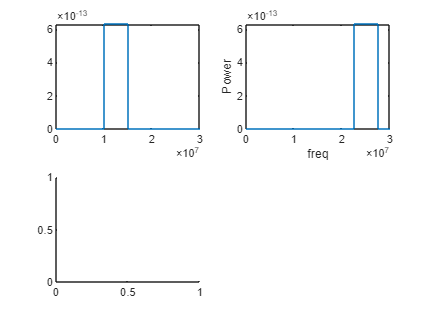

subplot(2,2,1)
plot(f,PSD_J1)
subplot(2,2,2)
plot(f,PSD_J2)
xlabel("freq")
ylabel("Power")


f = linspace(-30e6,30e6,length(Conv_J1_J1))

f =    -30000000   -29990000   -29980000   -29970000   -29960000   -29950000   -29940000   -29930000   -29920000   -29910000   -29900000   -29890000   -29880000   -29870000   -29860000   -29850000   -29840000   -29830000   -29820000   -29810000   -29800000   -29790000   -29780000   -29770000   -29760000   -29750000   -29740000   -29730000   -29720000   -29710000   -29700000   -29690000   -29680000   -29670000   -29660000   -29650000   -29640000   -29630000   -29620000   -29610000   -29600000   -29590000   -29580000   -29570000   -29560000   -29550000   -29540000   -29530000   -29520000   -29510000


subplot(2,2,1)
plot(f,Conv_J1_J1)
f = linspace(-30e6,30e6,length(Conv_J1J1_J2))

f = 1.0e+07 *

   -3.0000   -2.9993   -2.9987   -2.9980   -2.9973   -2.9967   -2.9960   -2.9953   -2.9947   -2.9940   -2.9933   -2.9927   -2.9920   -2.9913   -2.9907   -2.9900   -2.9893   -2.9887   -2.9880   -2.9873   -2.9867   -2.9860   -2.9853   -2.9847   -2.9840   -2.9833   -2.9827   -2.9820   -2.9813   -2.9807   -2.9800   -2.9793   -2.9787   -2.9780   -2.9773   -2.9767   -2.9760   -2.9753   -2.9747   -2.9740   -2.9733   -2.9727   -2.9720   -2.9713   -2.9707   -2.9700   -2.9693   -2.9687   -2.9680   -2.9673


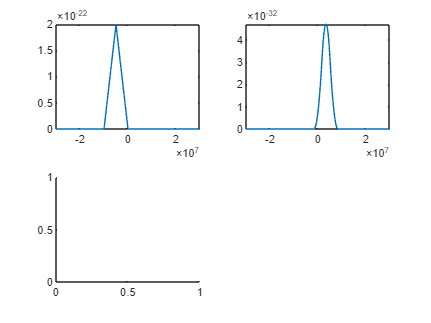

subplot(2,2,2)
plot(f,Conv_J1J1_J2)

nonZeroIndices = find(Conv_J1J1_J2 ~= 0);

% % Determine the starting index and length of consecutive non-zero values
% for i = 1:length(nonZeroIndices)
%     startIdx = nonZeroIndices(i);
%     endIdx = startIdx;
% 
%     % Check consecutive non-zero values
%     while endIdx < length(Conv_J1J1_J2) && Conv_J1J1_J2(endIdx + 1) ~= 0
%         endIdx = endIdx + 1;
%     end
% end
% trapz(linspace(0,1500,1),Conv_J1J1_J2(4751:6251))*10e6
trapz(Conv_J1J1_J2(4251+250:5751-250))*10^6

ans = 3.0090e-23